%{
ES 115 CLASS PROJECT PROBLEM 9.0
PROBLEM TITLE: Two Sensor Calibration and Agreement Check
DESCRIPTION: This project models two sensors measuring the same physical
             quantity using linear calibration equations. Each sensor output is modeled
             as a linear function of the true input, and their agreement is analyzed by
             comparing outputs and computing error across a range of input values
PURPOSE: To calibrate two sensor systems using known reference points, compare their 
         two outputs over a range of values, and evaluate measurement agreemnet by
         analyzing the error between the two models.
INPUTS:
    ~ Two calibration points for Sensor 1
    ~ Two Calibration points for sensor 2
    ~ Input Range: x = 0 to 30
OUTPUTS:
    ~ Calibration constants
    ~ Sensor output plots
    ~ Error function e(x)=y1-y2
    ~ Value of x where sensors agree best
ENGINNERING ALGORITHMS:
- Define two calibration points for each sensor
- Compute slope (m) and intercept (b) for both sensors
- Evaluate sensor models over a range of x values
- Compute error between sensor outputs
- Identify x value with minimum absolute error and plot results

MATLAB TOOLS/FUNCTIONS:
- Linear calibration
- Error analysis using absolute difference
- Numerical search for minimum error
%}


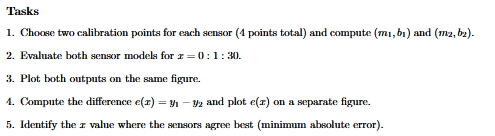

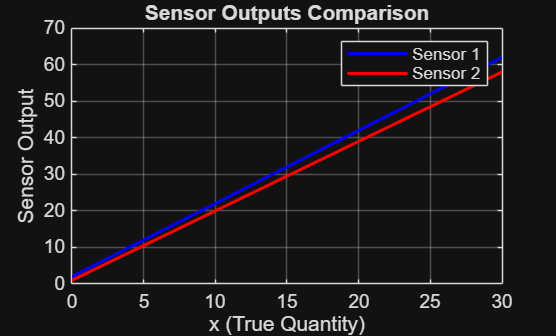

clc; clear; close all
% CALIBRATION POINTS (choose any realistic values)
% Sensor 1
x1_s1 = 0;   y1_s1 = 2;
x2_s1 = 30;  y2_s1 = 62;
% Sensor 2
x1_s2 = 0;   y1_s2 = 1;
x2_s2 = 30;  y2_s2 = 58;
% CALCULATE CALIBRATION CONSTANTS
% y = mx + b
% Compute slope and intercept from two calibration points
% Compute slope and intercept of line through the two sample points
% Note: division by zero if x2_s1 == x1_s1 (vertical line)
m1 = (y2_s1 - y1_s1) / (x2_s1 - x1_s1);
b1 = y1_s1 - m1*x1_s1;
% Compute slope and intercept for second sensor likewise
m2 = (y2_s2 - y1_s2) / (x2_s2 - x1_s2);
b2 = y1_s2 - m2*x1_s2;
% INPUT RANGE
x = 0:1:30;
% SENSOR MODELS
y1 = m1*x + b1;
y2 = m2*x + b2;
% ERROR FUNCTION
e = y1 - y2;
% Find x that minimizes absolute error between sensors
[~, idx] = min(abs(e));
x_best = x(idx);
% PLOTS
% Plot both sensor outputs for visual comparison
% Plot two sensor outputs versus x for visual comparison
figure
plot(x, y1, 'b', 'LineWidth', 1.5)
% Retain current axes to overlay second sensor trace
hold on
plot(x, y2, 'r', 'LineWidth', 1.5)
title('Sensor Outputs Comparison')
xlabel('x (True Quantity)')
ylabel('Sensor Output')
legend('Sensor 1','Sensor 2')
grid on

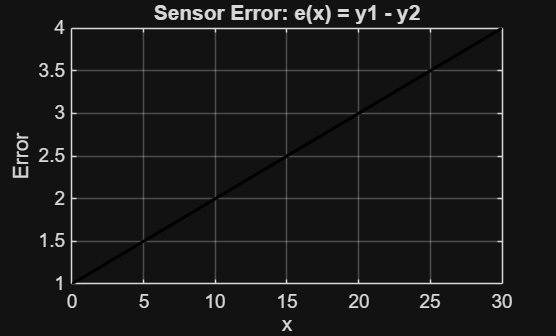

% Plot the pointwise error between the two sensors
% Plot sensor error e(x)=y1-y2 versus x using a solid black line
figure
plot(x, e, 'k', 'LineWidth', 1.5)
title('Sensor Error: e(x) = y1 - y2')
xlabel('x')
ylabel('Error')
% Enable grid for easier visual inspection
grid on

% OUTPUT RESULTS
% Print calibration constants and best agreement point
% Print calibration slopes, intercepts, and best-agreement x
fprintf('\n--- Calibration Results ---\n')


--- Calibration Results ---


fprintf('Sensor 1: m1 = %.3f, b1 = %.3f\n', m1, b1)

Sensor 1: m1 = 2.000, b1 = 2.000


fprintf('Sensor 2: m2 = %.3f, b2 = %.3f\n', m2, b2)

Sensor 2: m2 = 1.900, b2 = 1.000


fprintf('Best Agreement at x = %d\n', x_best)

Best Agreement at x = 0
